clear
close all

global K_A lim_H lim_K K_V_50kV K_V_2020 K_V_610E

% Angle gains
K_V_50kV = 5;
K_V_2020 = 2;
K_V_610E = 1;
K_A = 50/2.2; % 50deg / 2.2V <- DAC full range in Arduino Due

lim_H = [-35 5];
lim_K = [-35 5];





% 4M_raw_selfSensing_s_60kV_035Hz_1000Hz_050duty_005kVs_2022_11_09_2213
% 1234567890123456789012345678901234567890123456789012345678901234567890
% 0        1         2         3         4         5         6         7
FName = dir("4M*.dat")

FName = 7×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


fName = '4M_raw_selfSensing_s_30kV_005Hz_1000Hz_050duty_005kVs_2022_11_09_2210.dat'

tText = '3.0kV 0.5Hz'

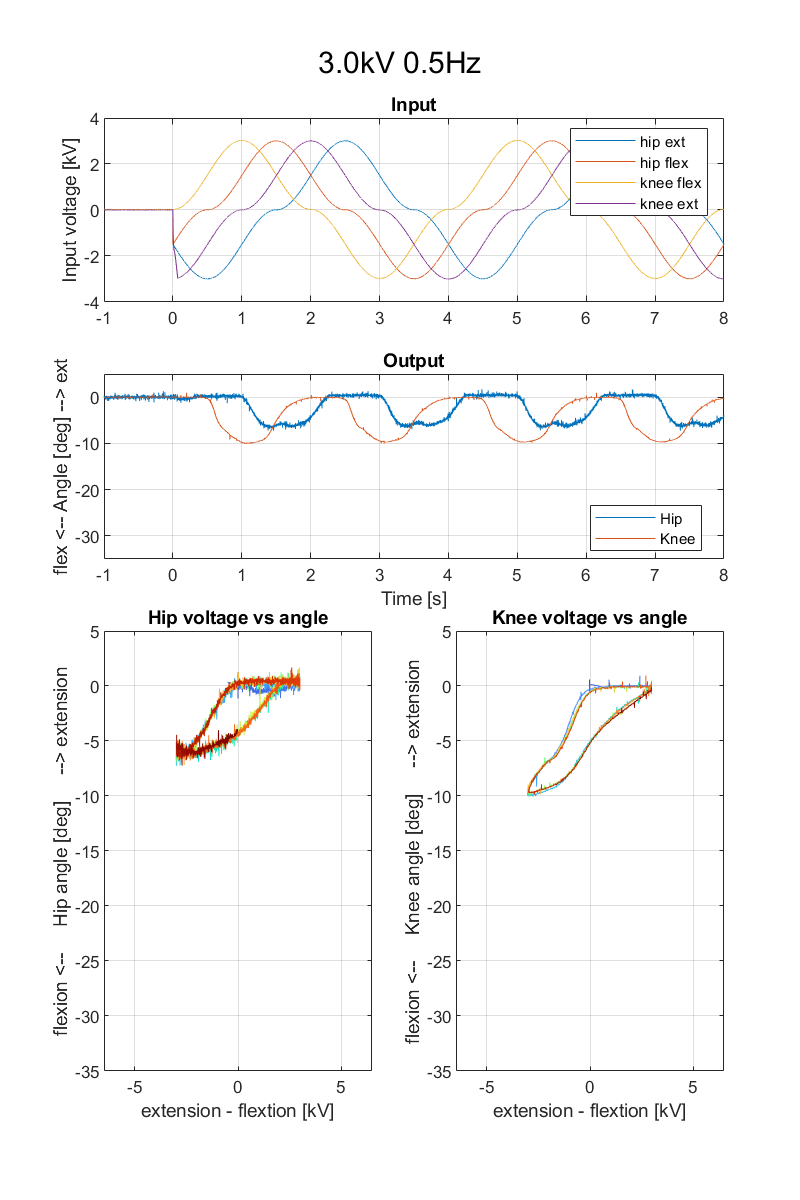

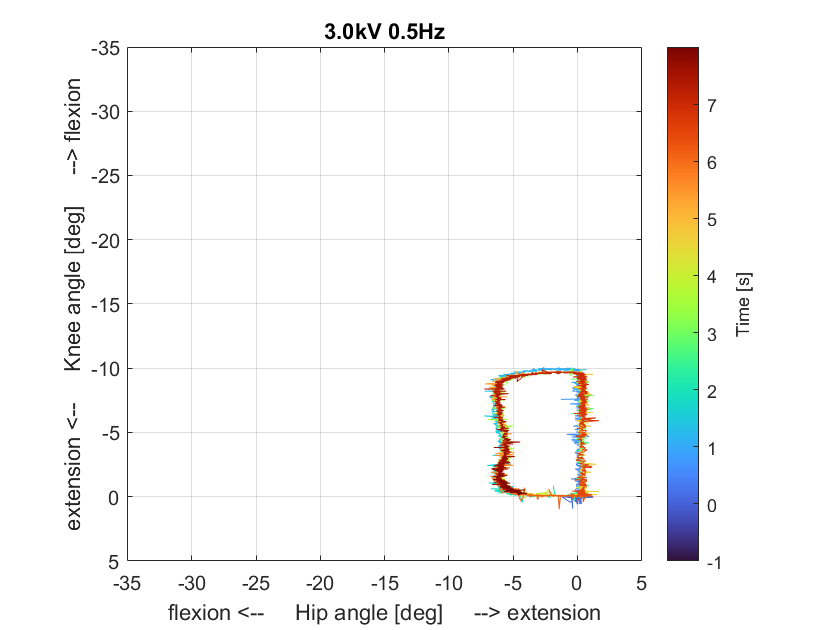

fName = '4M_raw_selfSensing_s_60kV_005Hz_1000Hz_050duty_005kVs_2022_11_09_2210.dat'

tText = '6.0kV 0.5Hz'

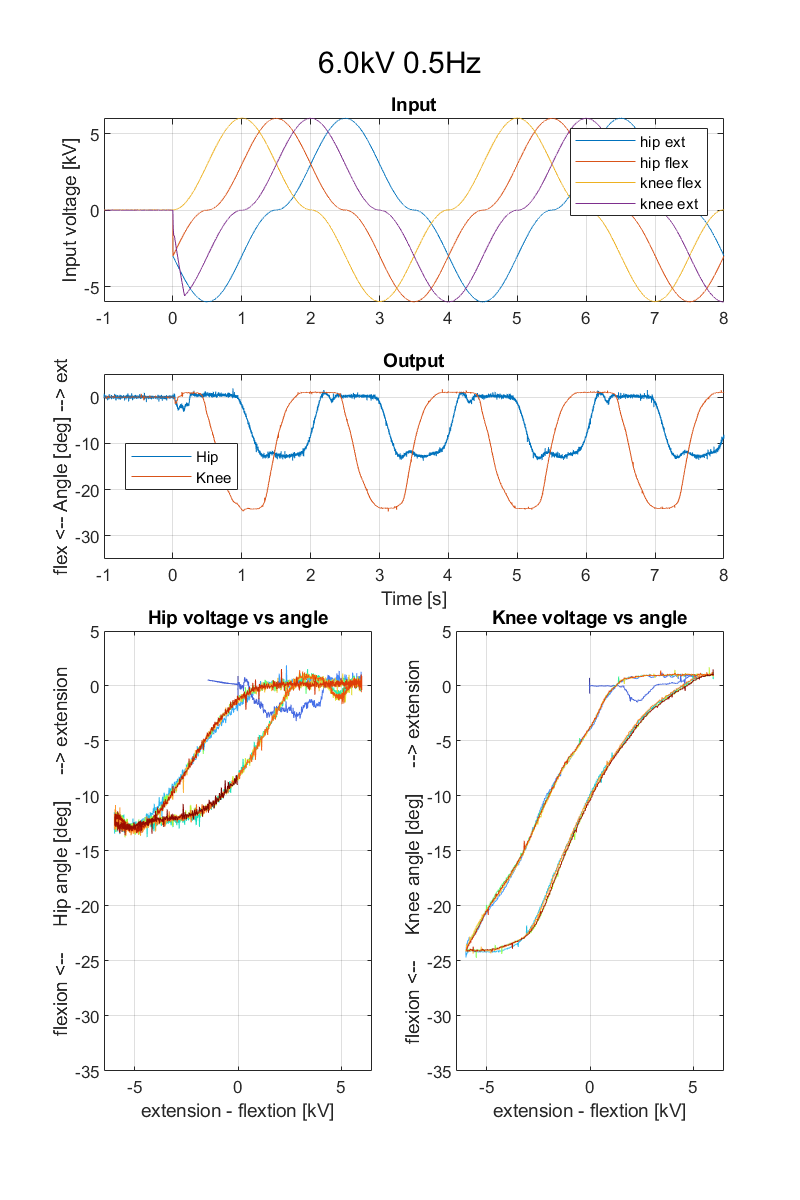

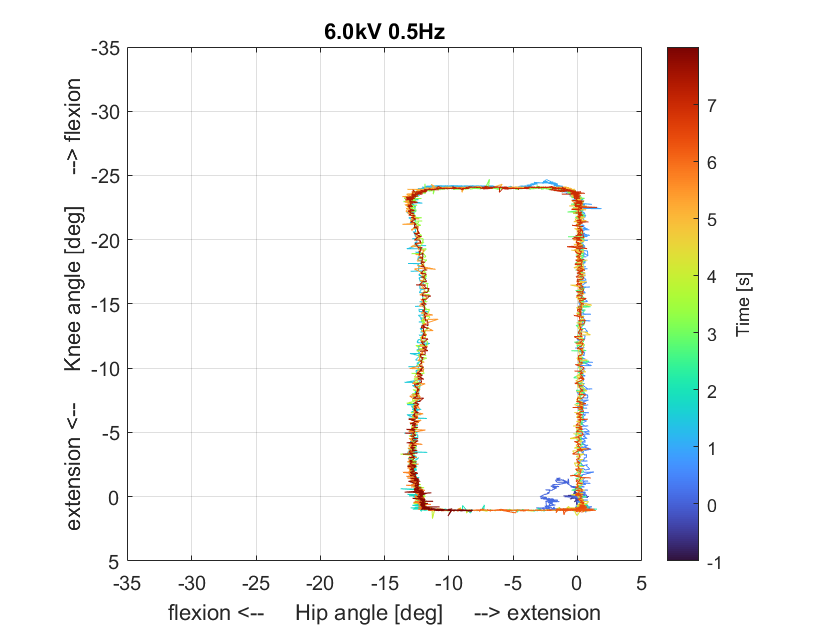

fName = '4M_raw_selfSensing_s_60kV_010Hz_1000Hz_050duty_005kVs_2022_11_09_2211.dat'

tText = '6.0kV 1.0Hz'

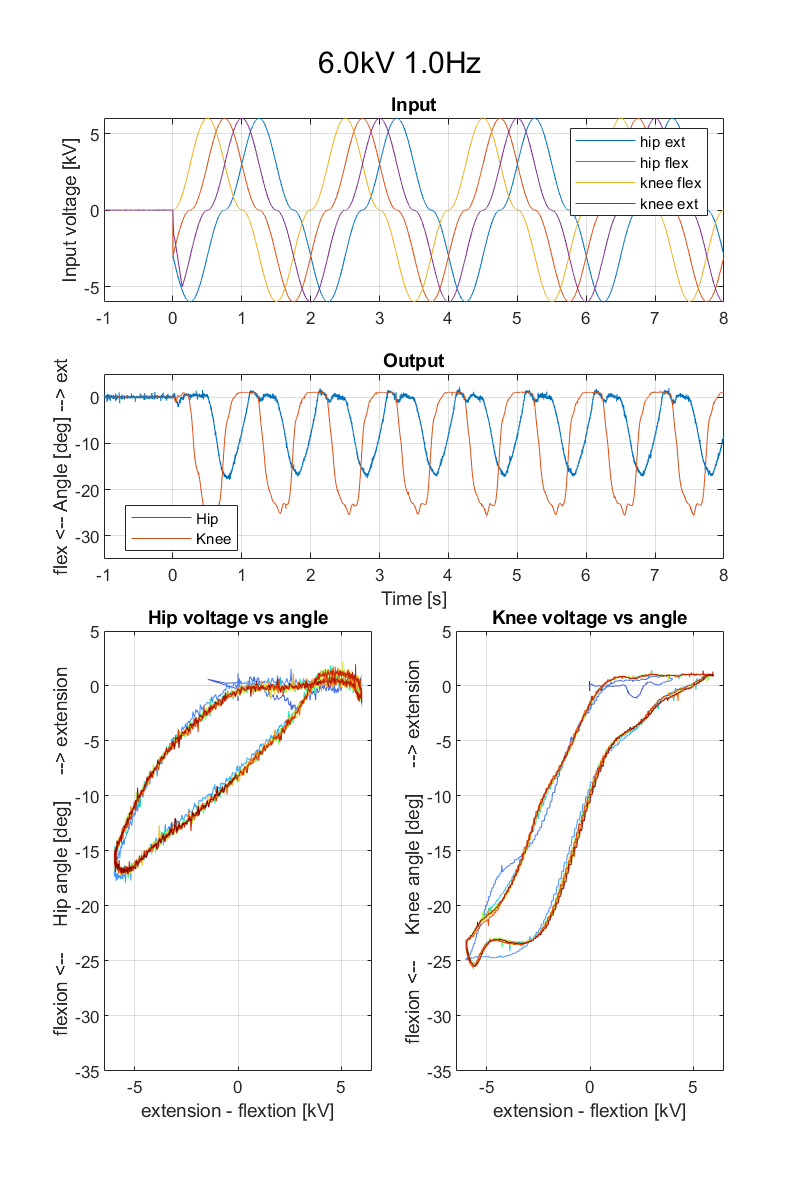

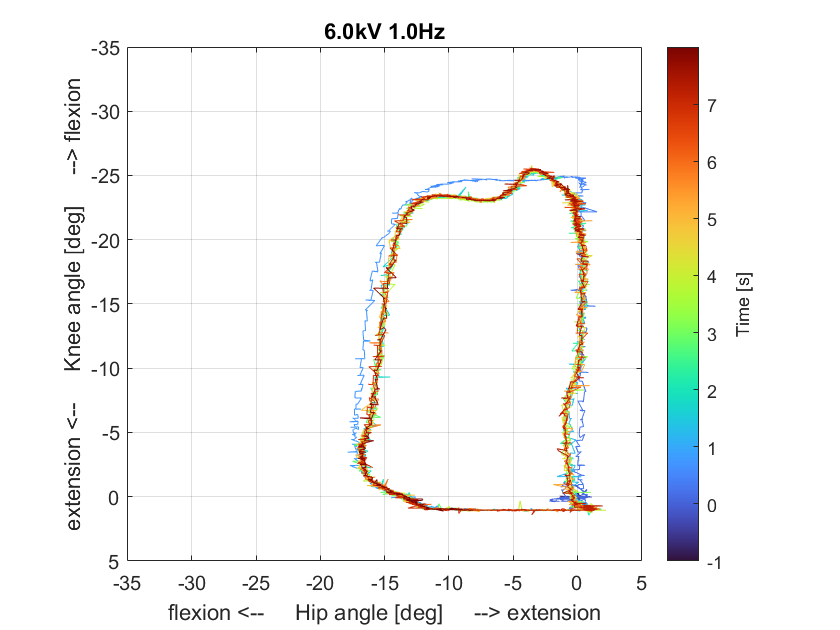

fName = '4M_raw_selfSensing_s_60kV_020Hz_1000Hz_050duty_005kVs_2022_11_09_2211.dat'

tText = '6.0kV 2.0Hz'

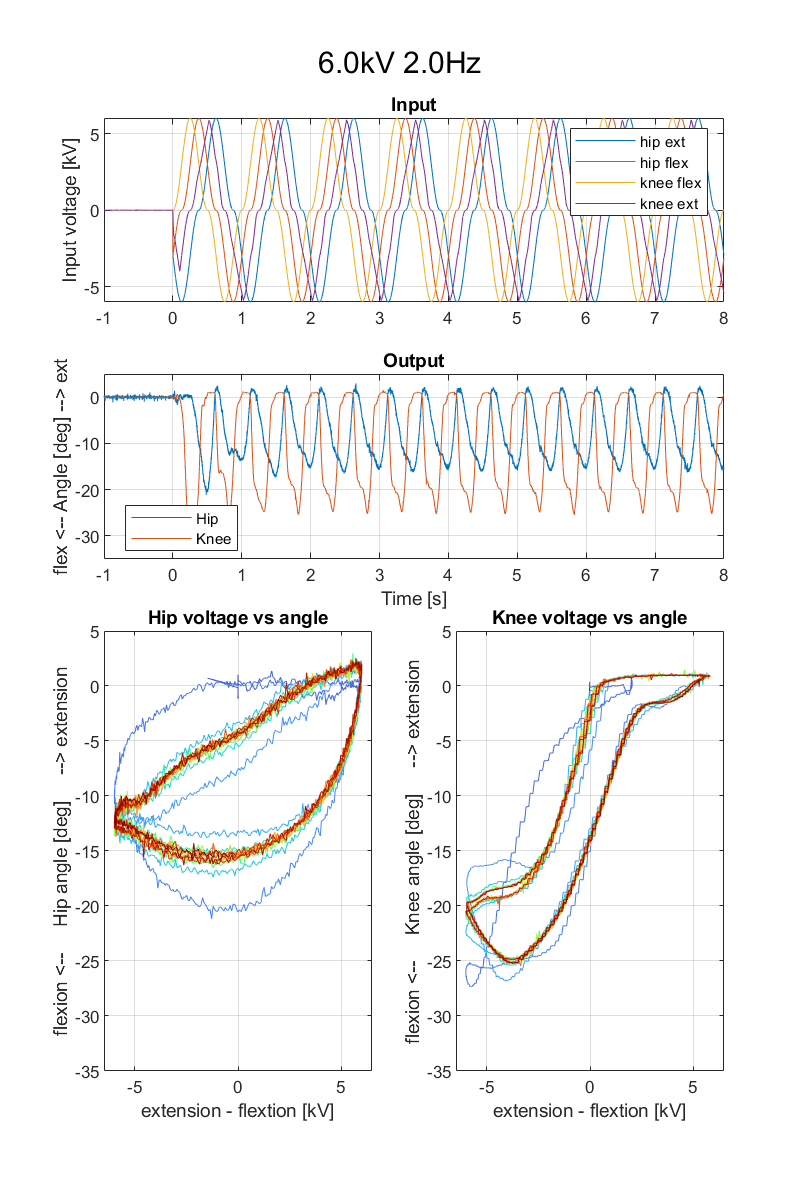

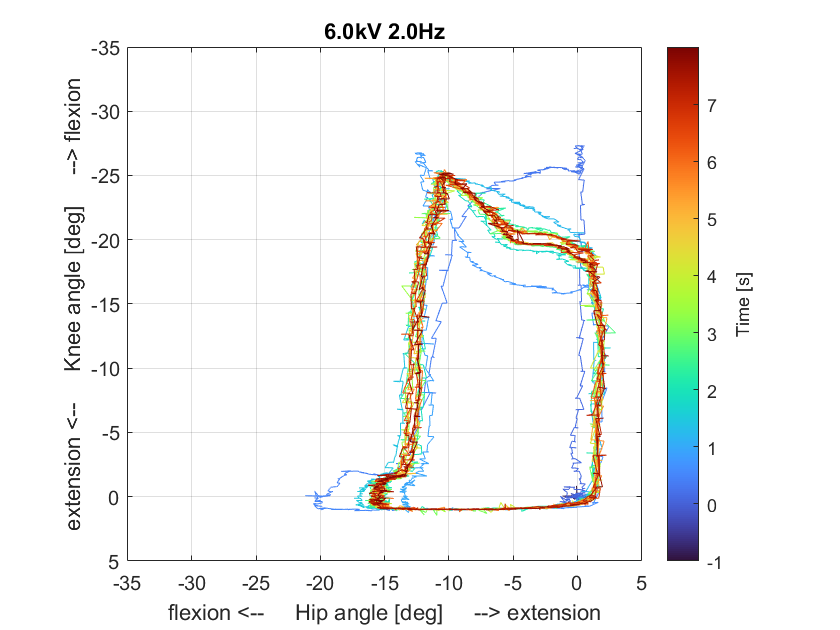

fName = '4M_raw_selfSensing_s_60kV_030Hz_1000Hz_050duty_005kVs_2022_11_09_2212.dat'

tText = '6.0kV 3.0Hz'

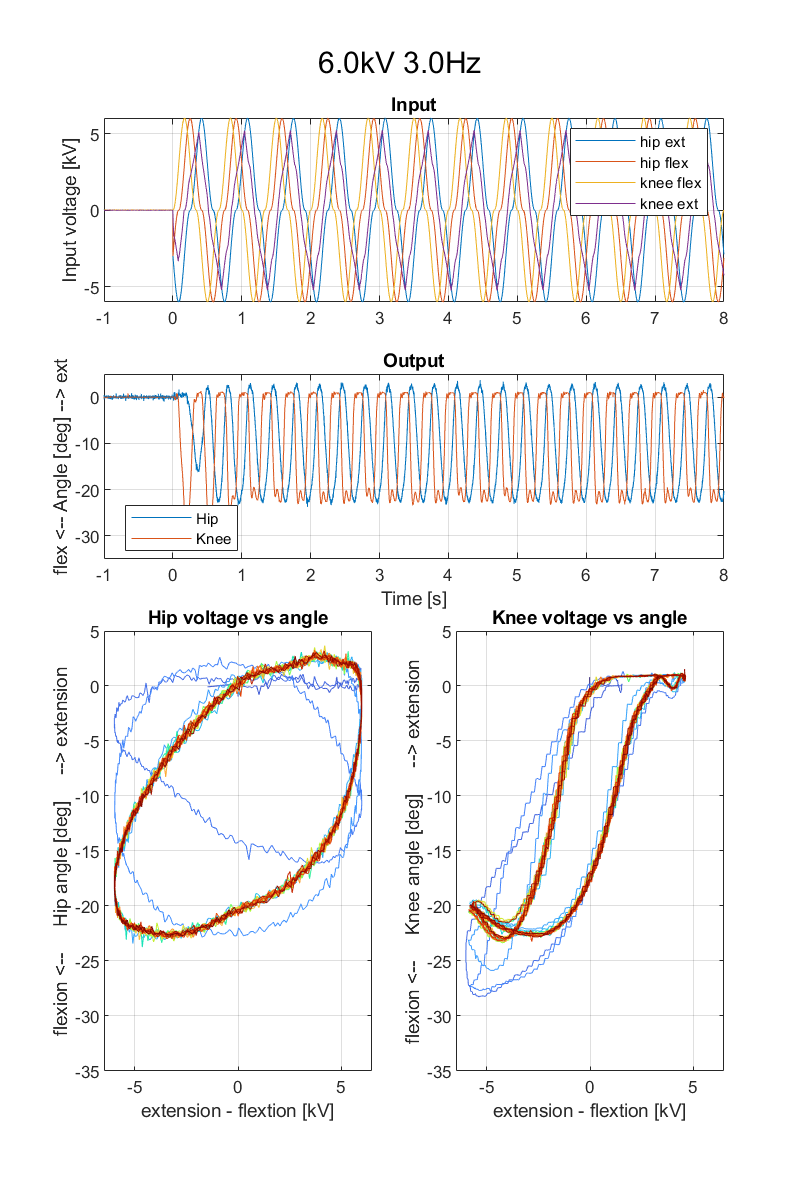

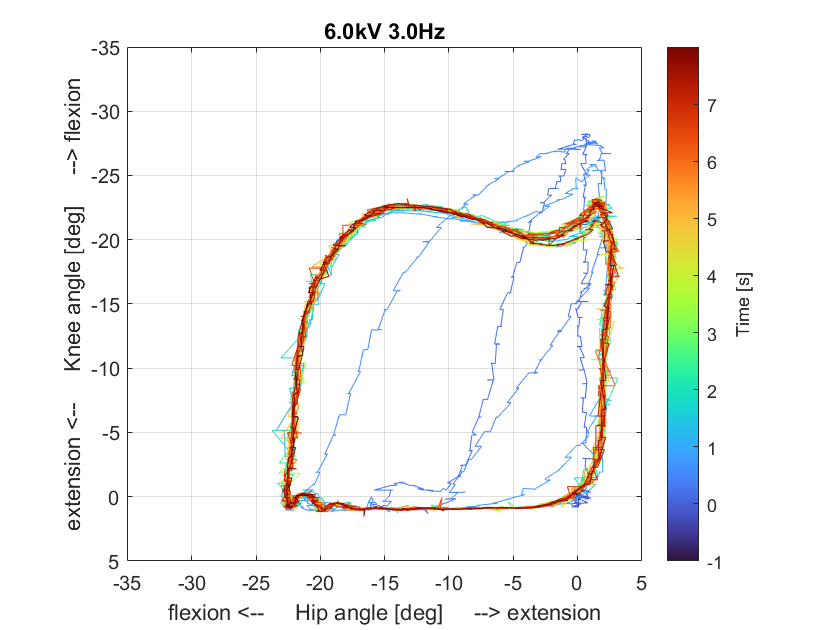

fName = '4M_raw_selfSensing_s_60kV_035Hz_1000Hz_050duty_005kVs_2022_11_09_2213.dat'

tText = '6.0kV 3.5Hz'

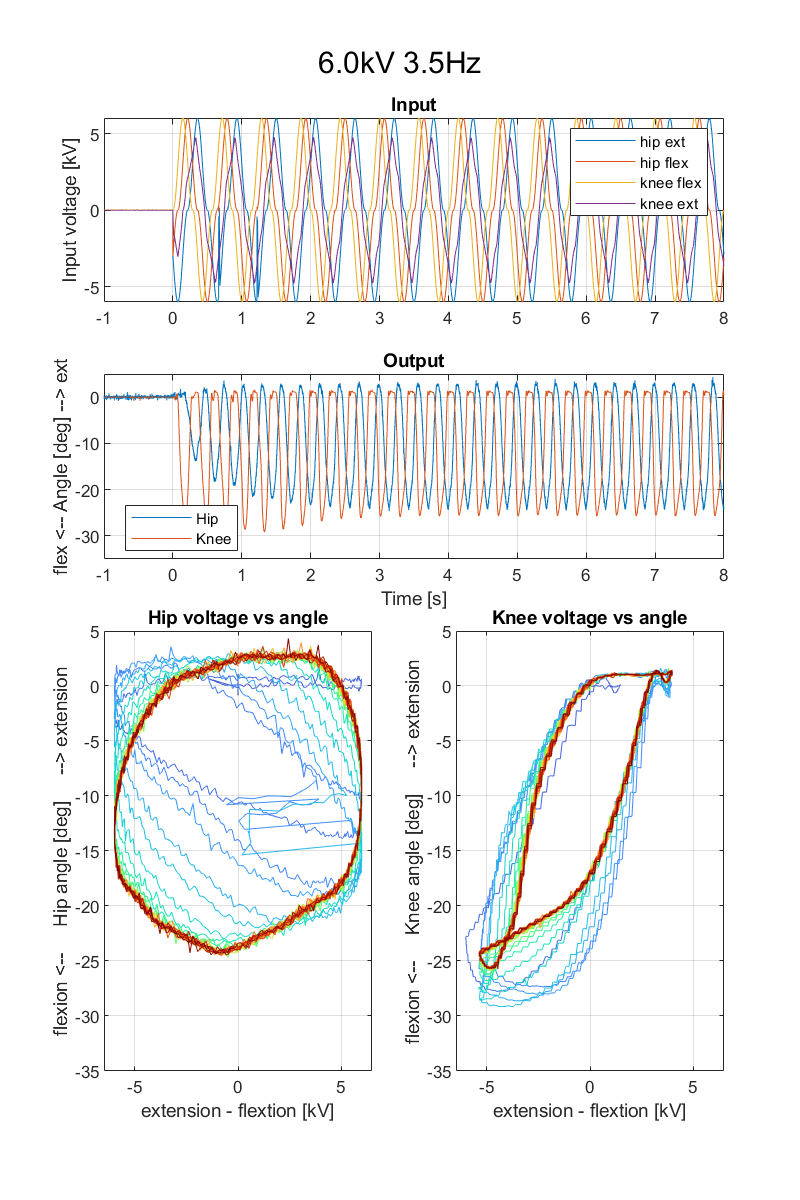

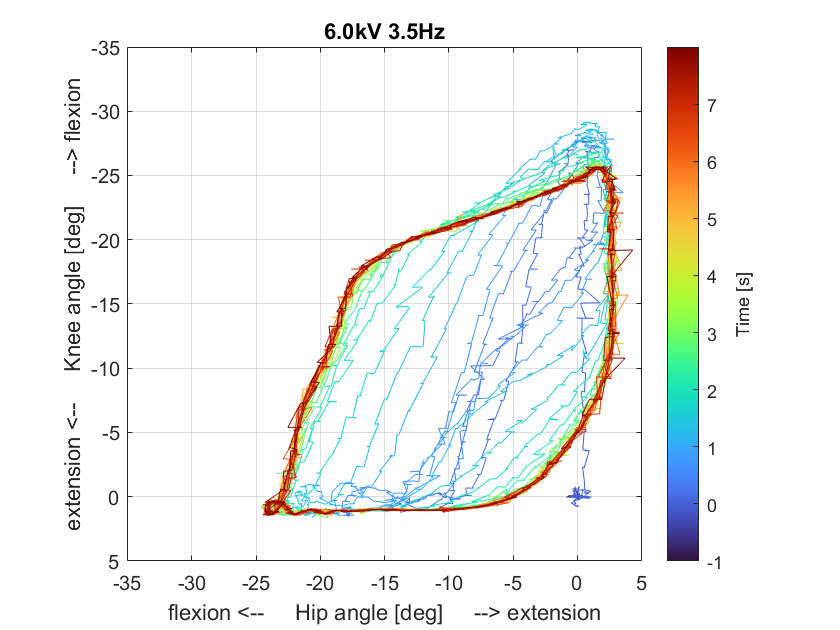

fName = '4M_raw_selfSensing_s_60kV_040Hz_1000Hz_050duty_005kVs_2022_11_09_2212.dat'

tText = '6.0kV 4.0Hz'

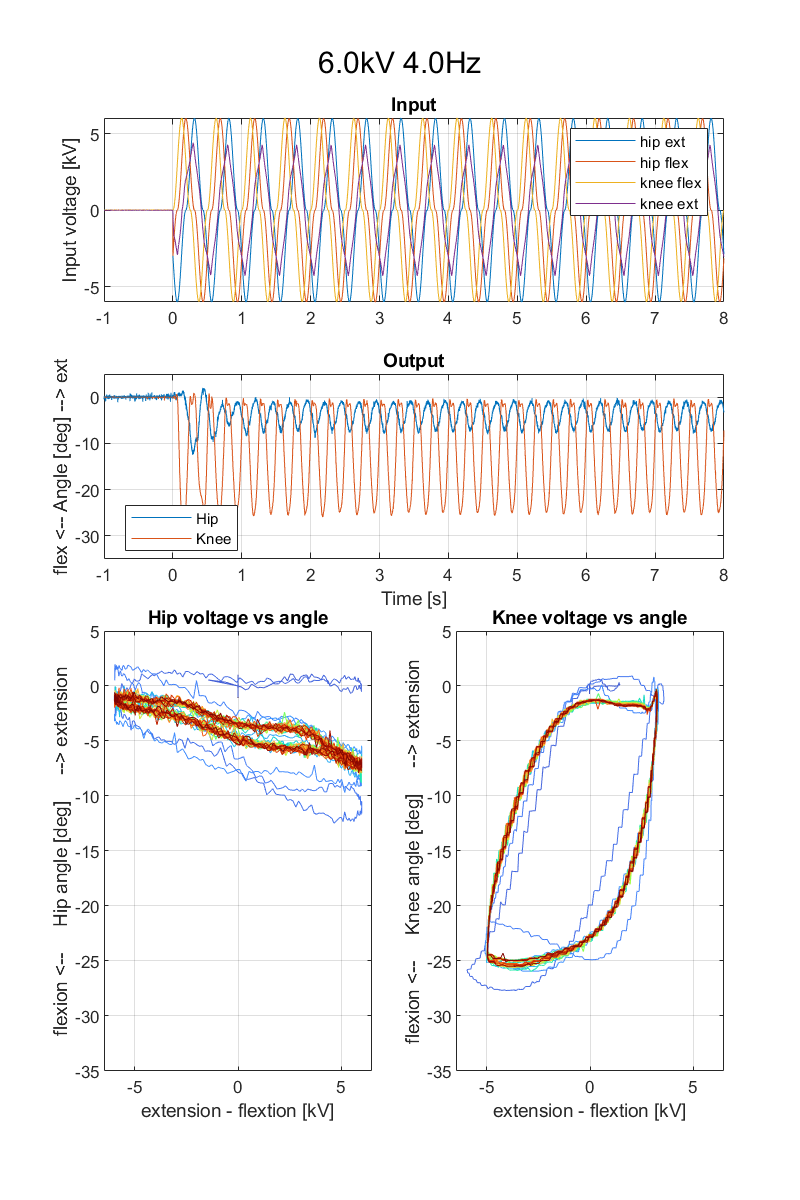

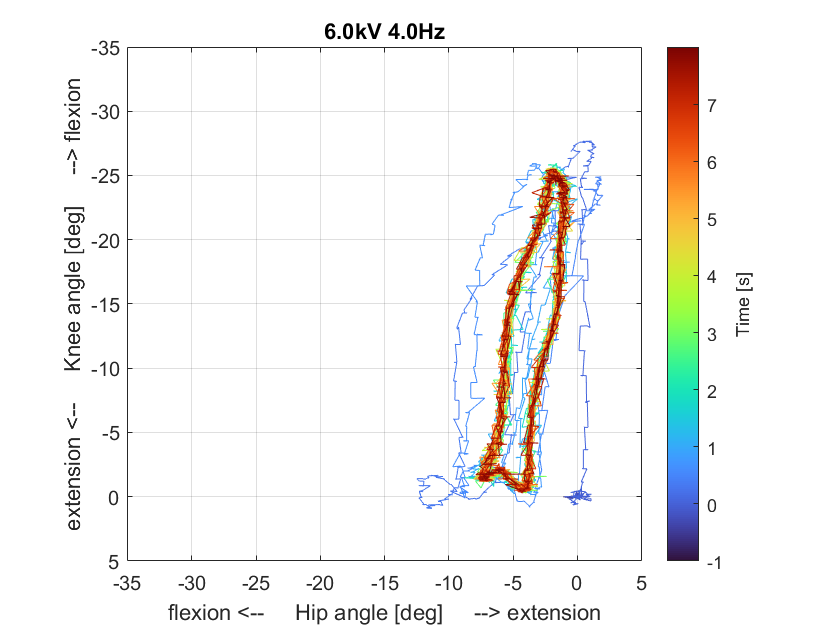


% FName = dir("4M_raw_selfSensing_s_60kV_005Hz_1000Hz_050duty_005kVs_2022_11_09_2210.dat")




figure(1)
clf
hold on

for i = 1: length(FName)
    fName = FName(i).name

    [Time, Voltage_HP_ref, Voltage_HP_act,  Voltage_HN_ref, Voltage_HN_act,  Voltage_KP_ref, Voltage_KP_act,  Voltage_KN_ref, Voltage_KN_act, Angle_H, Angle_K] = importfile(fName);

    maxVoltage = str2num(fName(22:23))/10;
    cycleFreq = str2num(fName(27:29))/10;

    tText = [num2str(maxVoltage, "%.1f"), 'kV ', num2str(cycleFreq, "%.1f"), 'Hz']



    f1 = figure(100 + i);
    clf
    f1.Position(4) = f1.Position(3)*1.5;

    ax1 = subplot(4, 2, 1:2);
    hold on
    plot(Time, Voltage_HP_act, "DisplayName", "hip ext")
    plot(Time, Voltage_HN_act, "DisplayName", "hip flex")
    plot(Time, Voltage_KP_act, "DisplayName", "knee flex")
    plot(Time, Voltage_KN_act, "DisplayName", "knee ext")
    legend()
    ylabel("Input voltage [kV]")
    box on
    grid on
    title("Input")

    ax2 = subplot(4, 2, 3:4);
    hold on
    plot(Time, Angle_H, "DisplayName", "Hip")
    plot(Time, Angle_K, "DisplayName", "Knee")
    ylim([min(lim_H(1), lim_K(1)), max(lim_K(2), lim_H(2))])
    xlabel("Time [s]")
    ylabel("flex <-- Angle [deg] --> ext")
    box on
    grid on
    title("Output")
    legend("Location", "best")

    ax3 = subplot(4, 2, [5, 7]);
    color_line(abs(Voltage_HP_act) - abs(Voltage_HN_act), Angle_H, Time);
    colormap("turbo")
    grid on
    box on
    xlim([-6.5 6.5])
    ylim(lim_H)
    title("Hip voltage vs angle")
    xlabel("extension - flextion [kV]")
    ylabel("flexion <--     Hip angle [deg]     --> extension")

    ax4 = subplot(4, 2, [6, 8]);
    color_line(abs(Voltage_KN_act) - abs(Voltage_KP_act), Angle_K, Time);
    colormap("turbo")
    grid on
    box on
    xlim([-6.5 6.5])
    ylim(lim_K)
    title("Knee voltage vs angle")
    xlabel("extension - flextion [kV]")
    ylabel("flexion <--     Knee angle [deg]     --> extension")

    sgtitle(tText)


    figure(200+i)
    color_line(Angle_H, Angle_K, Time);
    c = colorbar;
    c.Label.String = 'Time [s]';
    colormap("turbo")
    title(tText)
    ax = gca();
    ax.YDir = "reverse";
    grid on
    box on
    axis equal
    xlabel("flexion <--     Hip angle [deg]     --> extension")
    ylabel("extension <--     Knee angle [deg]     --> flexion")
    xlim(lim_H)
    ylim(lim_K)


    figure(1)
    plot(Angle_H, Angle_K, "DisplayName", tText)
end

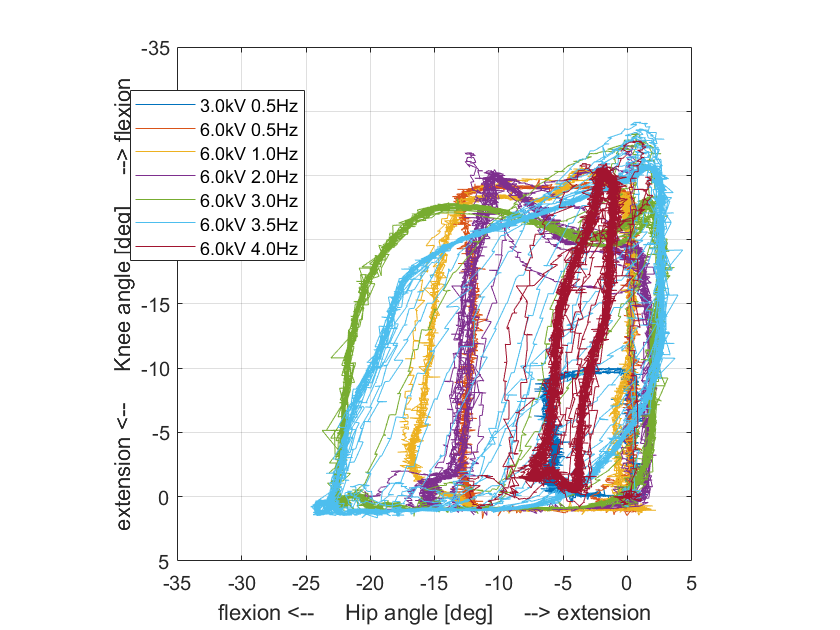


ax = gca;
legend("Location", "best")
ax.YDir = "reverse";
grid on
box on
axis equal
xlabel("flexion <--     Hip angle [deg]     --> extension")
ylabel("extension <--     Knee angle [deg]     --> flexion")
xlim(lim_H)
ylim(lim_K)

function [Time, Voltage_HP_ref, Voltage_HP_act,  Voltage_HN_ref, Voltage_HN_act,  Voltage_KP_ref, Voltage_KP_act,  Voltage_KN_ref, Voltage_KN_act, Angle_H, Angle_K] = importfile(fName)
global K_A lim_H lim_K K_V_50kV K_V_2020 K_V_610E

opts = delimitedTextImportOptions("NumVariables", 15);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["Times", "VoltageRef1kV", "VoltageRef2kV", "VoltageRef3kV", "VoltageRef4kV", "Voltage1kV", "Current1A", "Voltage2kV", "Current2A", "Voltage3kV", "Current3A", "Voltage4kV", "Current4A", "Angle1V", "Angle2V"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Import the data
tbl = readtable(fName, opts);


Times = tbl.Times;
VoltageRef1kV = tbl.VoltageRef1kV;
VoltageRef2kV = tbl.VoltageRef2kV;
VoltageRef3kV = tbl.VoltageRef3kV;
VoltageRef4kV = tbl.VoltageRef4kV;
Voltage1kV = tbl.Voltage1kV;
Current1A = tbl.Current1A;
Voltage2kV = tbl.Voltage2kV;
Current2A = tbl.Current2A;
Voltage3kV = tbl.Voltage3kV;
Current3A = tbl.Current3A;
Voltage4kV = tbl.Voltage4kV;
Current4A = tbl.Current4A;
Angle1V = tbl.Angle1V;
Angle2V = tbl.Angle2V;


Time = Times;
Angle_H = (Angle1V - mean(Angle1V(1: 500)))*K_A;
Angle_K = -(Angle2V - mean(Angle2V(1: 500)))*K_A;

Voltage_KP_ref = VoltageRef1kV*K_V_50kV;
Voltage_KP_act = Voltage1kV*K_V_50kV;
Voltage_HN_ref = VoltageRef2kV*K_V_610E;
Voltage_HN_act = Voltage2kV*K_V_610E;
Voltage_KN_ref = VoltageRef3kV*K_V_610E;
Voltage_KN_act = Voltage3kV*K_V_610E;
Voltage_HP_ref = VoltageRef4kV*K_V_2020;
Voltage_HP_act = Voltage4kV*K_V_2020;


end